# **TAP 1**

**Integrantes:**

- Jeffrey Antonio Monja Castro

- Angello Giovanni Soldi Cataño

- Juan Carlos Paredes Alva

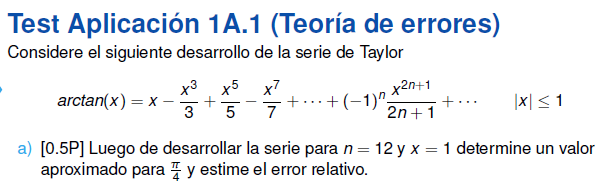

format long

n = 12;
x = 1;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exact = atan(x);

fprintf('La función arctan(x) aproximada para x = 1 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = 1 y n = 12 es: 0.804601

fprintf('La función arctan(x) exacta para x = 1 es: %f', arctan_exact);

La función arctan(x) exacta para x = 1 es: 0.785398

x = pi/4;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exacto = atan(x);
delta = abs(arctan_exacto - arctan_aprox)/abs(arctan_exacto);

fprintf('La función arctan(x) aproximada para x = pi/4 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = pi/4 y n = 12 es: 0.665808

fprintf('El error relativo es: %f', delta);

El error relativo es: 0.000052

csig = 5;

terminos = arctan_taylor_nterm(x, csig);

fprintf('Nro de términos para aproximar arctan(x) es: %d', terminos);

Nro de términos para aproximar arctan(x) es: 15


% Comprobación
arctan_taylor_it(x, terminos);
atan(x);

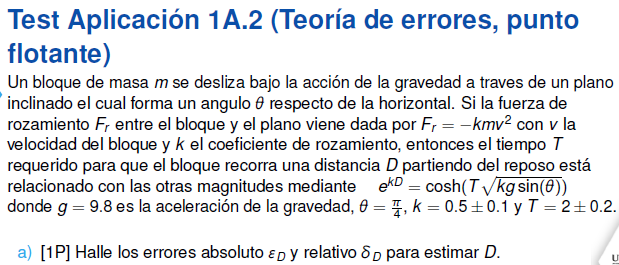

format long
g = 9.8; 
theta = pi/4;
k1 = 0.5; error_k = 0.1;
T1 = 2; error_T = 0.2;

syms T k
D = 1/k * log(cosh(T * sqrt(k * g * sin(theta))));
D = matlabFunction(D);

dD_T = matlabFunction(diff(D,T));
dD_k = matlabFunction(diff(D,k));

delta_D = abs(dD_T(T1,k1)) * error_k + abs(dD_k(T1,k1)) * error_T;

errorabs_D = delta_D * D(T1, k1);

fprintf('Error absoluto de la función D: %f', errorabs_D);

Error absoluto de la función D: 7.931097

fprintf('Error relativo de la función D: %f', delta_D);

Error relativo de la función D: 1.308657

intervalo_inferior = D(T1, k1) - errorabs_D;
intervalo_superior = D(T1, k1) + errorabs_D;

fprintf('Intervalo de confianza para D: [%f, %f]', intervalo_inferior, intervalo_superior)

Intervalo de confianza para D: [-1.870609, 13.991584]

syms p
M = 10^p * (delta_D/errorabs_D);
M = matlabFunction(M);

n = M(4);

fprintf("El número M es: %f", n);

El número M es: 1650.032266


% IEEE-754 precisión simple
bin_simple = simple2binary(n);

fprintf("IEEE-754 simple: %s", bin_simple);

IEEE-754 simple: 01000100110011100100000100001000


% Comprobando la función inversa de binario simple a decimal
bin2dec_simple = binary2dec_simple(num2str(bin_simple));

fprintf("De IEEe-754 simple a decimal: %f", bin2dec_simple)

De IEEe-754 simple a decimal: 1650.032227


% IEEE-754 precisión doble
bin_doble = double2binary(n);

fprintf("IEEE-754 doble: %s", bin_doble);

IEEE-754 doble: 0100000010011001110010000010000100001010001111011011011100110010


% Comprobando la función inversa de binario doble a decimal
bin2dec_double = binary2dec_double(num2str(bin_doble));

fprintf("De IEEe-754 simple a decimal: %f", bin2dec_double)

De IEEe-754 simple a decimal: 1650.032266

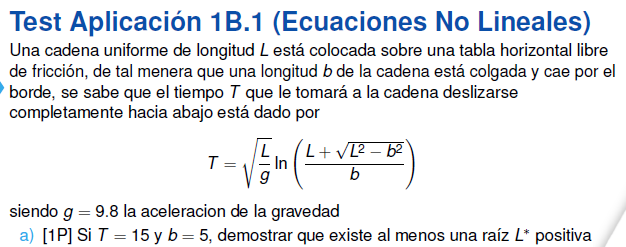

syms L
T = 15;
b = 5;
g = 9.8;

f = sqrt(L/g) * log((L + sqrt(L^2 - b^2))/b) - T

$$f = \log\left(\frac{L}{5}+\frac{\sqrt{L^{2}-25}}{5}\right)\,\sqrt{\frac{5\,L}{49}}-15$$

f = matlabFunction(f);

% Teorema de bolzano weierstrass
if (f(0) * f(1000) < 0)
    fprintf("Existe al menos una raíz L positiva")
else 
    fprintf("No existe")
end

Existe al menos una raíz L positiva

Tol = 10^-5;
a = 130;
b = 140;

biseccion(f, a, b, Tol)

Se necesita 19 iteraciones


ans = 1.0e+02 *

   1.300000000000000   1.400000000000000   1.350000000000000  -0.006102985392862   0.002131934839032  -0.001960098177999   0.050000000000000
   1.350000000000000   1.400000000000000   1.375000000000000  -0.001960098177999   0.002131934839032   0.000092129161369   0.025000000000000
   1.350000000000000   1.375000000000000   1.362500000000000  -0.001960098177999   0.000092129161369  -0.000932414020317   0.012500000000000
   1.362500000000000   1.375000000000000   1.368750000000000  -0.000932414020317   0.000092129161369  -0.000419752058004   0.006250000000000
   1.368750000000000   1.375000000000000   1.371875000000000  -0.000419752058004   0.000092129161369  -0.000163714134285   0.003125000000000
   1.371875000000000   1.375000000000000   1.373437500000000  -0.000163714134285   0.000092129161369  -0.000035768192651   0.001562500000000
   1.373437500000000   1.375000000000000   1.374218750000000  -0.000035768192651   0.000092129161369   0.000028186553483   0.000781250000

newt = newton(f, 90, Tol)

fprintf("Valor de L aproximado con tolerancia de 10^-5: %f", newt(end))

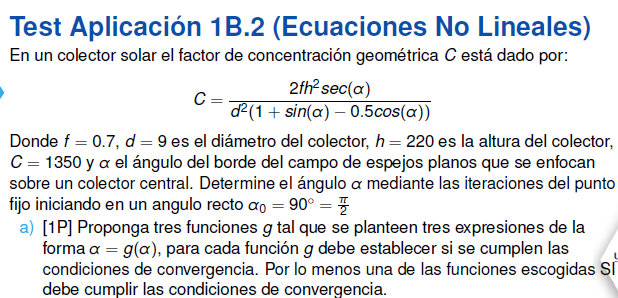

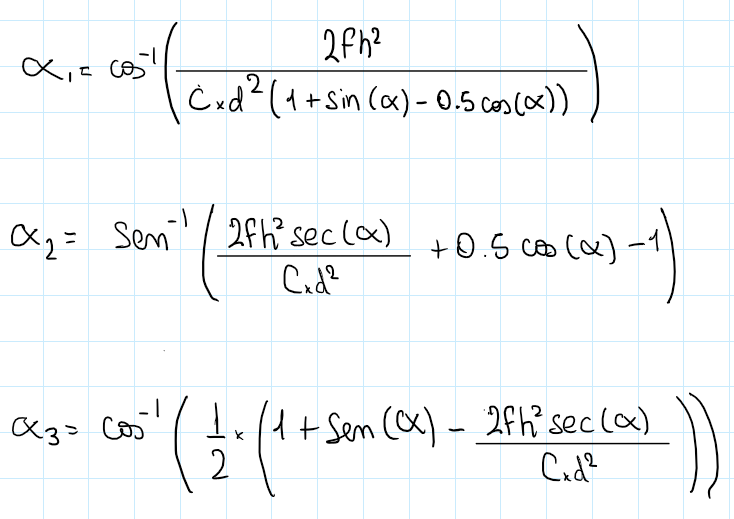


$$\text{Primer criterio de convergencia:} = |g'(x)| < 1$$



$$\text{Segundo criterio de convergencia: } \forall x \in [a,b] \rightarrow g(x) \in [a,b]$$


syms a

f = 0.7;
d = 9;
h = 220;

$$f1 = \frac{67760}{\cos\left(a\right)\,\left(109350\,\sin\left(a\right)-54675\,\cos\left(a\right)+109350\right)}$$

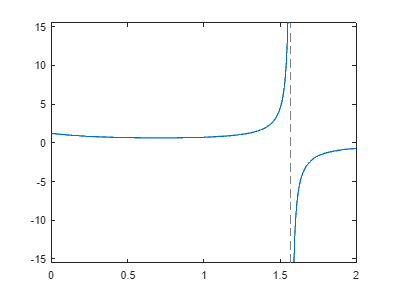

C = 1350;

f1 = (2*f*h^2*sec(a))/(C*d^2*(1+sin(a)-0.5*cos(a)))


f1 = matlabFunction(f1);
intervalo = [0 2];
fplot(f1,intervalo)

**Primera función**

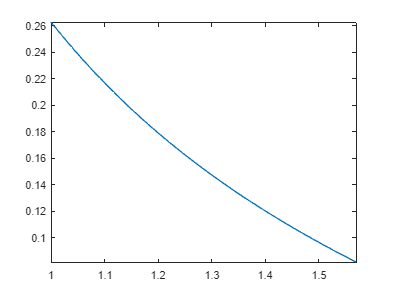

g1 = acos((2*f*h^2)/(C*d^2*(1+sin(a) - 0.5*cos(a))));
g1 = matlabFunction(g1);

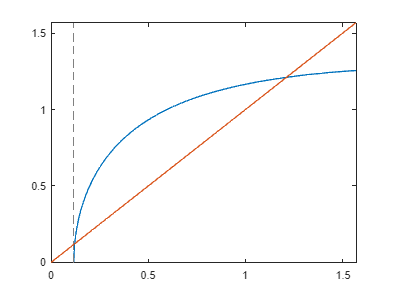


% Primer criterio
dg1 = matlabFunction(diff(g1(a)));
fplot(dg1,[1 pi/2])

% Segundo criterio

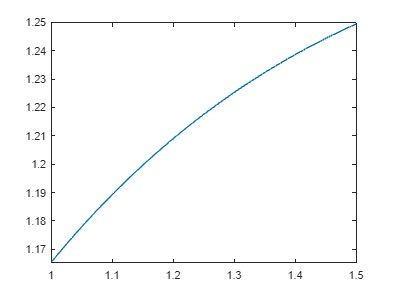

fplot(g1,[0 pi/2])

hold on 
fplot(x, [0 pi/2])
hold off
fplot(g1,[1 1.5])

La propuesta g1 sí converge para el intervalo [1 1.5]

**Segunda función**

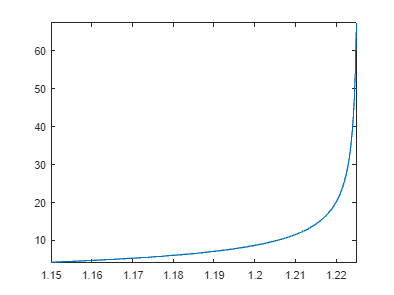

g2 = asin((2*f*h^2*sec(a))/(C*d^2) + 0.5*cos(a) - 1);
g2 = matlabFunction(g2);

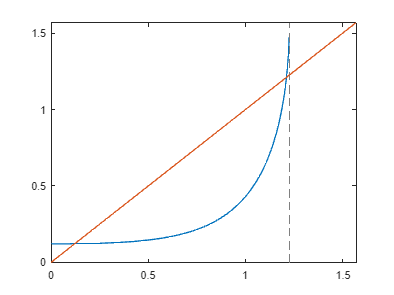


% Primer criterio
dg2 = matlabFunction(diff(g2(a)));
fplot(dg2,[1.15 1.225])

% Segundo criterio

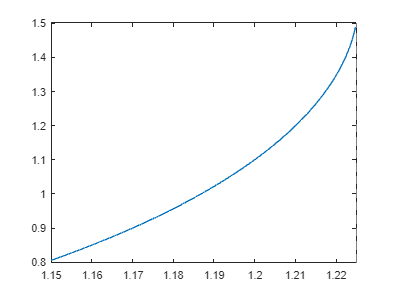

fplot(g2,[0 pi/2])

hold on 
fplot(x, [0 pi/2])
hold off
fplot(g2,[1.15 1.225])

La propuesta g2 no converge en el intervalo [1.15 1.225]

**Tercera función**

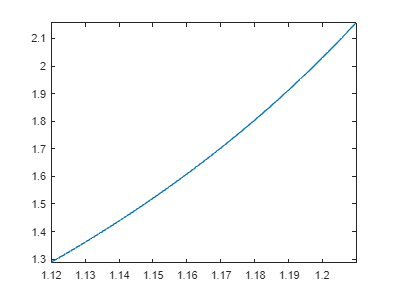

g3 = acos(1/2 * (1 + sin(a) - (2*f*h^2*sec(a))/(C*d^2)));
g3 = matlabFunction(g3);

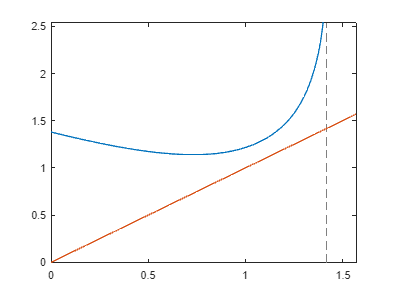


% Primer criterio
dg3 = matlabFunction(diff(g3(a)));
fplot(dg3,[1.12 1.21])

% Segundo criterio

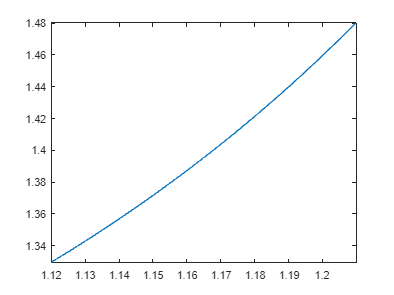

fplot(g3,[0 pi/2])

hold on 
fplot(f_indentidad, [0 pi/2])
hold off
fplot(g3,[1.12 1.21])

La propuesta g3 no converge en el intervalo [1.12 1.21]

a0 = 1.2109822042165;
Tol = 10^-8;

sol = puntofijo(g1, a0, Tol);


La aproximación de la raíz es 1.210985

fprintf('La aproximación de la raíz es %f', sol(end, 1))

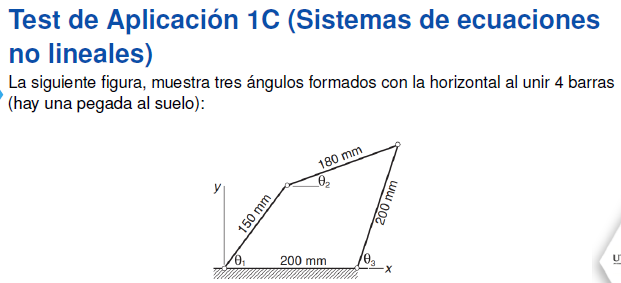

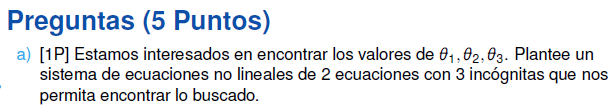

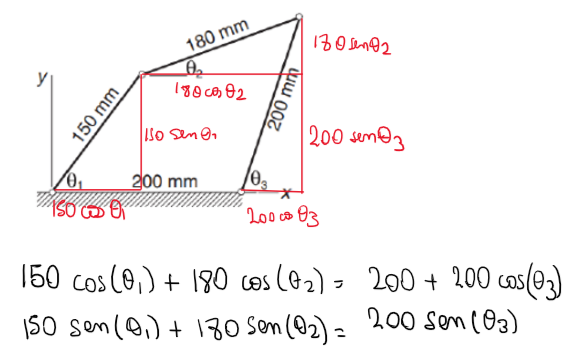

syms x y z
F = [150*cos(x) + 180*cos(y) - 200 - 200*cos(z); 150*sin(x) + 180*sin(y) - 200*sin(z)];
disp(F)

$$\left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-200\,\cos\left(z\right)-200\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-200\,\sin\left(z\right) \end{array}\right)$$

z1 = deg2rad(75);
F = [150*cos(x) + 180*cos(y) - 200 - 200*cos(z1); 150*sin(x) + 180*sin(y) - 200*sin(z1)];
disp(F)

$$\left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-\frac{35432606140316225}{140737488355328}\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-\frac{849637342059177}{4398046511104} \end{array}\right)$$

F = matlabFunction(F);

J = jacobian(F(x,y),[x,y]);
disp(J)

$$\left(\begin{array}{cc} -150\,\sin\left(x\right) & -180\,\sin\left(y\right)\\ 150\,\cos\left(x\right) & 180\,\cos\left(y\right) \end{array}\right)$$

tol = 1e-3;

%Punto 1
% se elije (0,2) porque es un número que está en el intervalo que proporciona ángulos indicados
x0 = [0;2];
z1 = newtonraphson(F,x0,tol);
sol1 = [z1(end,1) z1(end,2)];
fprintf("Solución 1:\ntheta_1 = %f, theta_2 = %f", rad2deg(sol1))

Solución 1:
theta_1 = 20.018783, theta_2 = 51.996899


%Punto 2
x0 = [1;0];
z2 = newtonraphson(F,x0,tol);
sol2 = [z2(end,1) z2(end,2)];
fprintf("Solución 1:\ntheta_1 = %f, theta_2 = %f", rad2deg(sol2))

Solución 1:
theta_1 = 54.981221, theta_2 = 23.003098

Ambos puntos proporcionan respuestas que son menores a 180° sexagesimales, cumpliendo la regla de la suma interna de ángulos de los triángulos

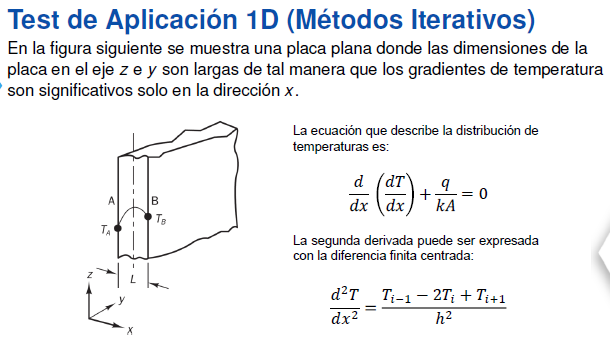

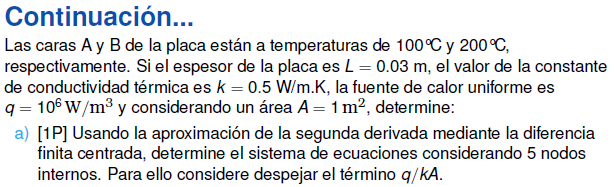

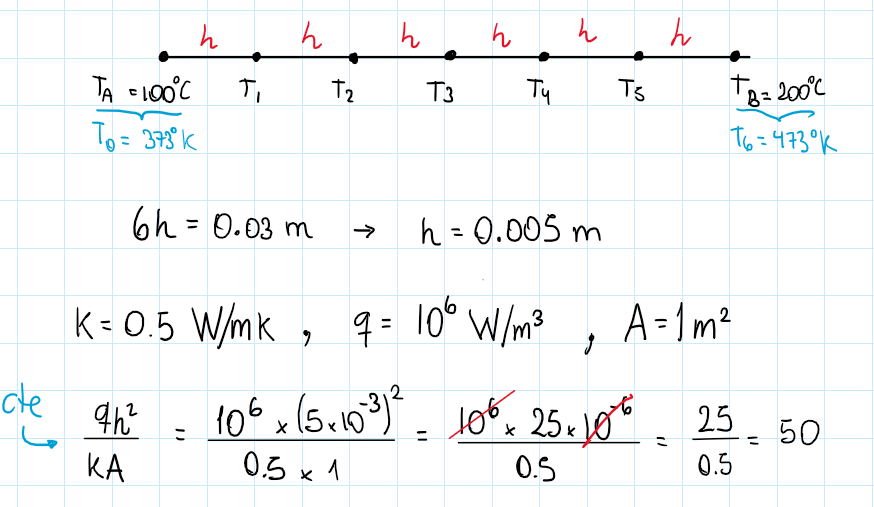

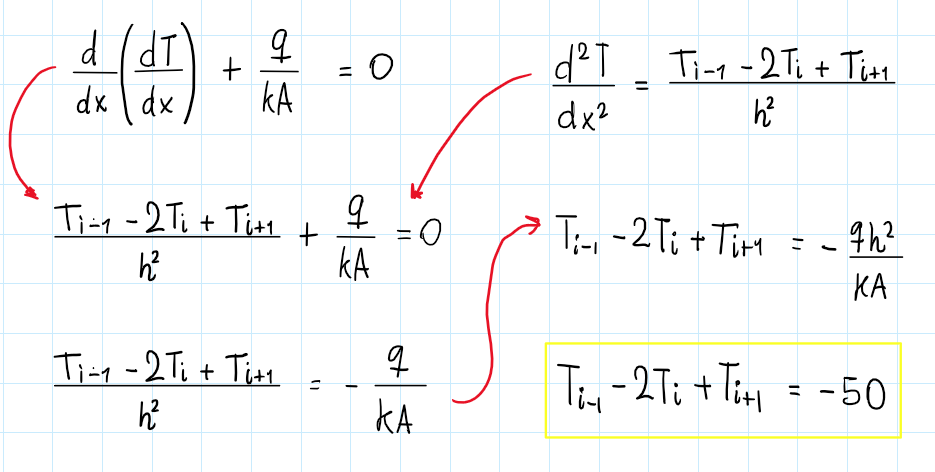

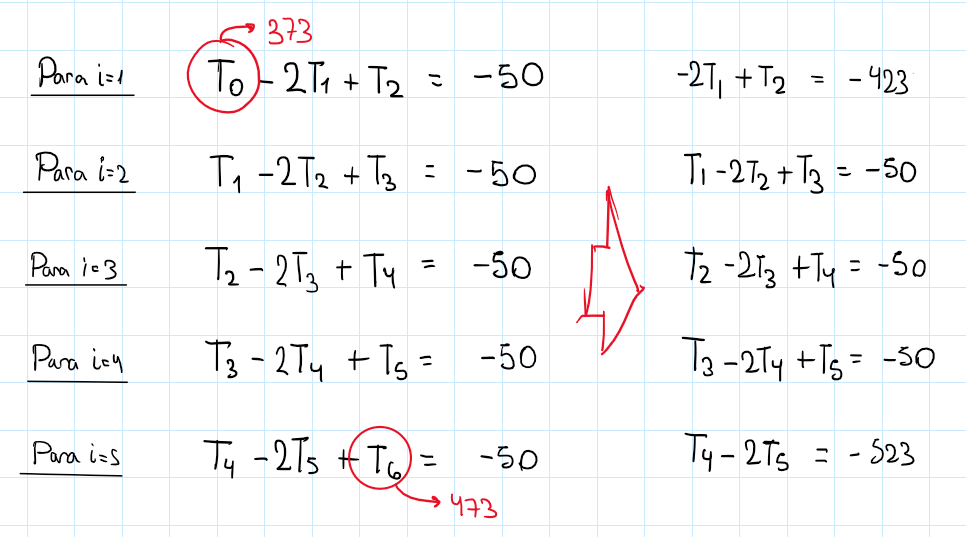

L = 0.03; k = 0.5; A = 1; q = 10^6;
h = L/6;

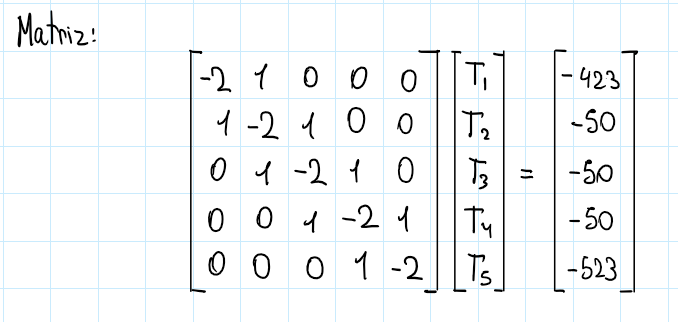

A = [-2 1 0 0 0
     1 -2 1 0 0
     0 1 -2 1 0
     0 0 1 -2 1
     0 0 0 1 -2];
b = [-423 -50 -50 -50 -523]';

fprintf("Matriz A\n")

Matriz A


disp(A)

    -2     1     0     0     0
     1    -2     1     0     0
     0     1    -2     1     0
     0     0     1    -2     1
     0     0     0     1    -2




fprintf("Matriz b\n")

Matriz b


disp(b)

  -423
   -50
   -50
   -50
  -523



if (~diagdom(A))
    fprintf("La matriz converge")
else
    fprintf("No se puede afirmar nada")
end

No se puede afirmar nada

grad = 100 + 273;
x0 = [grad grad grad grad grad]';
Tol = 1e-3;

z = jacobi(A, b, x0, Tol)

z = 1.0e+02 *

   3.730000000000000   3.730000000000000   3.730000000000000   3.730000000000000   3.730000000000000   0.010000000000000
   3.980000000000000   3.980000000000000   3.980000000000000   3.980000000000000   4.480000000000000   0.001674107142857
   4.105000000000000   4.230000000000000   4.230000000000000   4.480000000000000   4.605000000000000   0.001085776330076
   4.230000000000000   4.417500000000000   4.605000000000000   4.667500000000000   4.855000000000000   0.000772399588054
   4.323750000000000   4.667500000000000   4.792500000000000   4.980000000000000   4.948750000000000   0.000627510040161
   4.448750000000000   4.808125000000000   5.073750000000000   5.120625000000000   5.105000000000000   0.000549249359209
   4.519062500000000   5.011250000000000   5.214375000000000   5.339375000000000   5.175312500000000   0.000409692145616
   4.620625000000000   5.116718750000000   5.425312500000000   5.444843750000000   5.284687500000000   0.000387407811289
   4.673359375000


aprox = z(end, 1:5);

fprintf("T1 = %f\nT2 = %f\nT3 = %f\nT4 = %f\nT5 = %f\n", aprox)

T1 = 513.163277
T2 = 603.827684
T3 = 644.993221
T4 = 637.161018
T5 = 579.829944


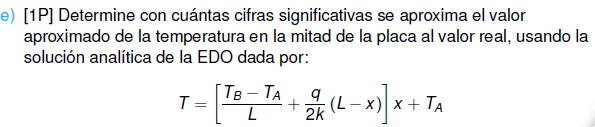

syms x
Ta = 100 + 273; Tb = 200 + 273;
T = ((Tb - Ta)/L + (q/(2*k))*(L-x))*x + Ta

$$T = 373-x\,\left(1000000\,x-\frac{100000}{3}\right)$$

T = matlabFunction(T);

X = 0.005:0.005:0.025;
exacto = T(X);

fprintf("T1 = %f\nT2 = %f\nT3 = %f\nT4 = %f\nT5 = %f\n", exacto)

T1 = 514.666667
T2 = 606.333333
T3 = 648.000000
T4 = 639.666667
T5 = 581.333333



% Cifras significativas
cs = floor(-log10(abs(exacto(3)-aprox(3))/(5*abs(exacto(3)))));

fprintf("En la mitad de la placa, el valor aproximado se aproxima en %d cifras significativas", cs)

En la mitad de la placa, el valor aproximado se aproxima en 3 cifras significativas

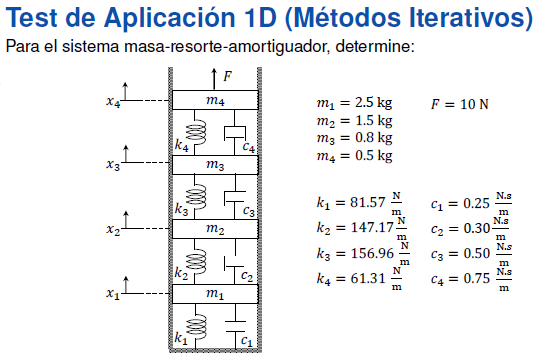

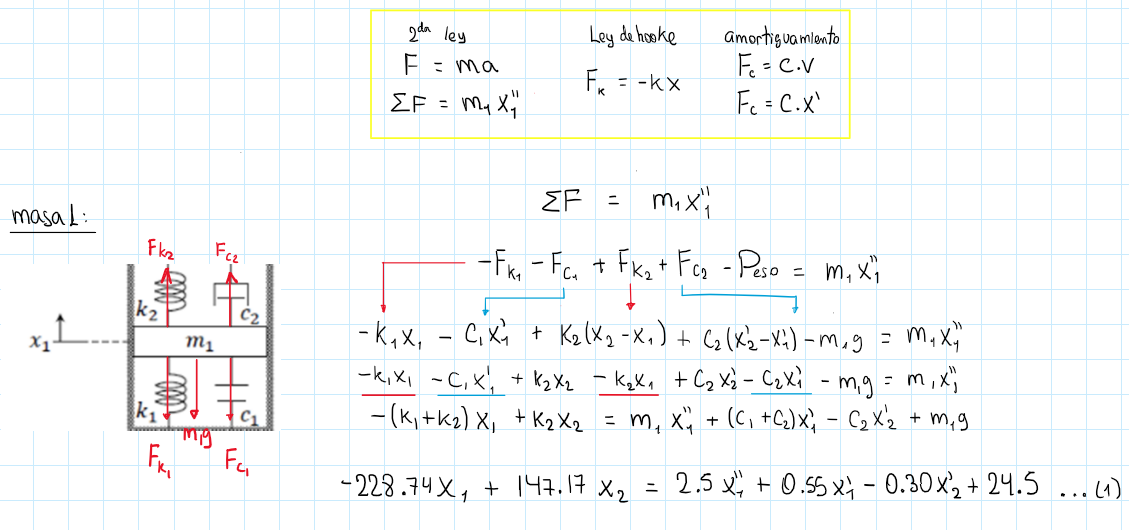

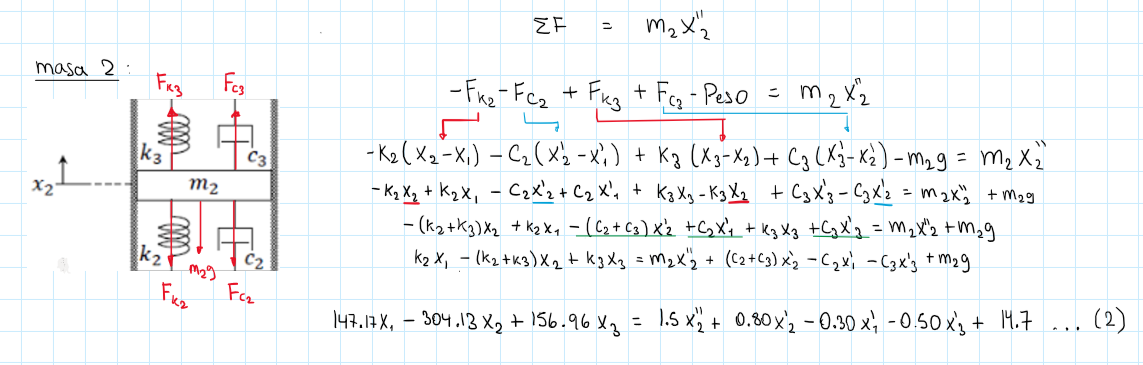

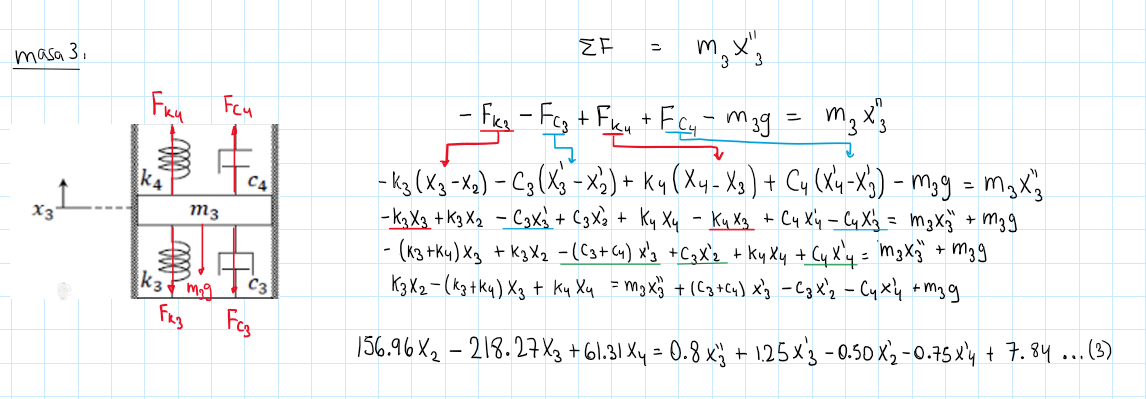

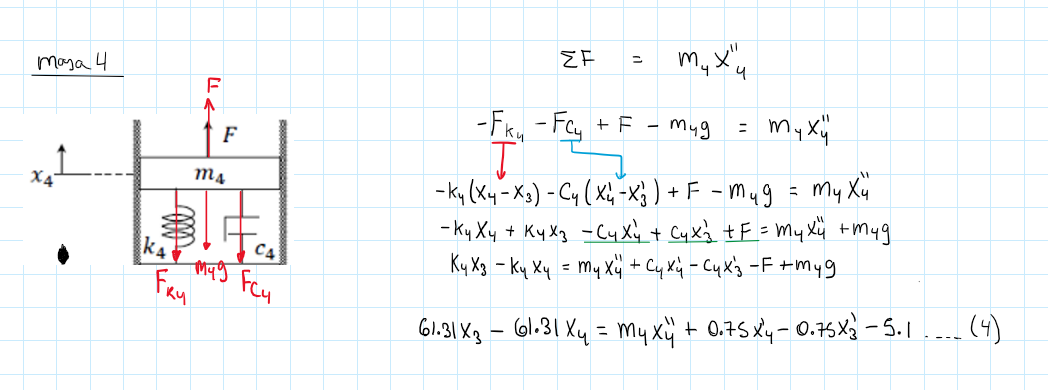

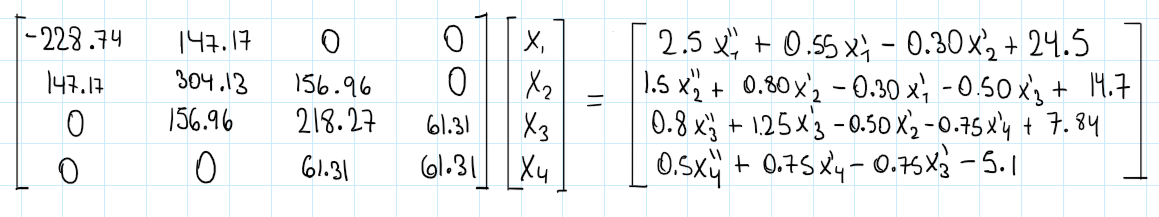

m1 = 2.5; m2 = 1.5; m3 = 0.8; m4 = 0.5;
k1 = 81.57; k2 = 147.17; k3 = 156.96; k4 = 61.31;
c1 = 0.25; c2 = 0.50; c3 = 0.70; c4 = 0.75;
F = 10;

A = [-(k1 + k2) k2 0 0;
     k2 -(k2 + k3) k3 0;
     0 k3 -(k3 + k4) k4;
     0 0 k4 -k4];

syms dx ddx

b = [2.5*ddx + 0.55*dx - 0.30*dx + 24.5
     1.5*ddx + 0.80*dx - 0.30*dx - 0.50*dx + 14.7
     0.8*ddx + 1.25*dx - 0.50*dx - 0.75*dx + 7.84
     0.5*ddx + 0.75*dx - 0.75*dx - 5.1];

fprintf("Matriz A\n")

Matriz A


disp(A)

   1.0e+02 *

  -2.287400000000000   1.471700000000000                   0                   0
   1.471700000000000  -3.041300000000000   1.569600000000000                   0
                   0   1.569600000000000  -2.182700000000000   0.613100000000000
                   0                   0   0.613100000000000  -0.613100000000000




fprintf("Matriz b\n")

Matriz b


disp(b)

$$\left(\begin{array}{c} \frac{5\,\mathrm{ddx}}{2}+\frac{\mathrm{dx}}{4}+\frac{49}{2}\\ \frac{3\,\mathrm{ddx}}{2}+\frac{147}{10}\\ \frac{4\,\mathrm{ddx}}{5}+\frac{196}{25}\\ \frac{\mathrm{ddx}}{2}-\frac{51}{10} \end{array}\right)$$

b = matlabFunction(b);
b = b(0, 0)

b =   24.500000000000000
  14.699999999999999
   7.840000000000000
  -5.100000000000000



[Ea,nb] = gauss(A, b);
x = sustireg(Ea, nb);

fprintf("Eliminación gaussiana\nx1 = %f\nx2 = %f\nx3 = %f\nx4 = %f\n", x)

Eliminación gaussiana
x1 = -0.514160
x2 = -0.632662
x3 = -0.650119
x4 = -0.566935


D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);

Tgs = inv(D-L)*U;

rho_Tgs = radio_espectral(Tgs);

if (rho_Tgs > 1)
    fprintf("No converge")
else
    fprintf("Si converge. Valor: %f", rho_Tgs)
end

Si converge. Valor: 0.861895

x0 = [0.1 0.1 0.1 0.1]';
Tol = 1e-3;

gs = gausseidel(A,b,x0,Tol);

fprintf("Gauss Seidel\nx1 = %f\nx2 = %f\nx3 = %f\nx4 = %f\n", gs(end, 1:4))

Gauss Seidel
x1 = -0.511705
x2 = -0.629373
x3 = -0.646610
x4 = -0.563426


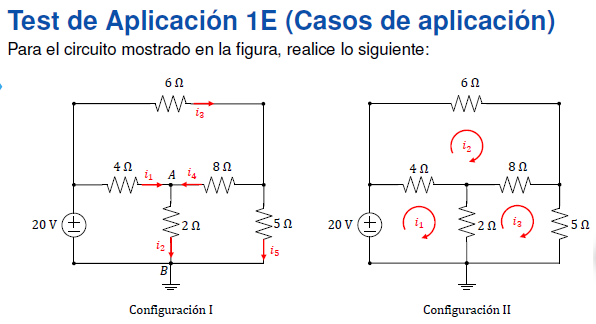

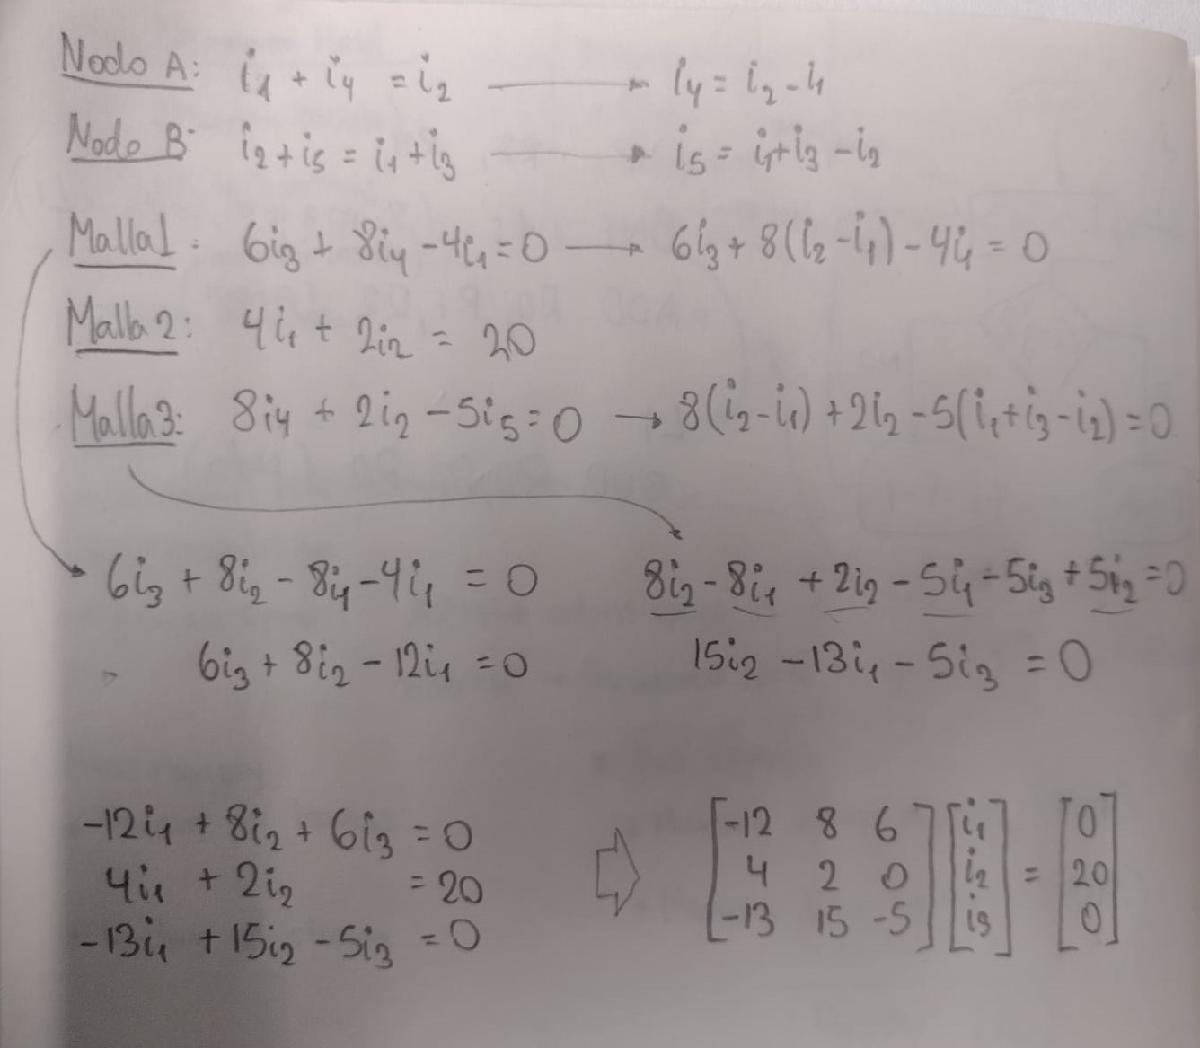

A = [-12 8 6; 4 2 0; -13 15 -5];
b = [0 20 0]';

fprintf("Matriz A\n")

Matriz A


disp(A)

   -12     8     6
     4     2     0
   -13    15    -5




fprintf("Matriz b\n")

Matriz b


disp(b)

     0
    20
     0



[Ea,nb] = gauss(A, b);
x = sustireg(Ea, nb);   

fprintf("Eliminación gaussiana\ni1 = %f\ni2 = %f\ni3 = %f", x)

Eliminación gaussiana
i1 = 3.266332
i2 = 3.467337
i3 = 1.909548

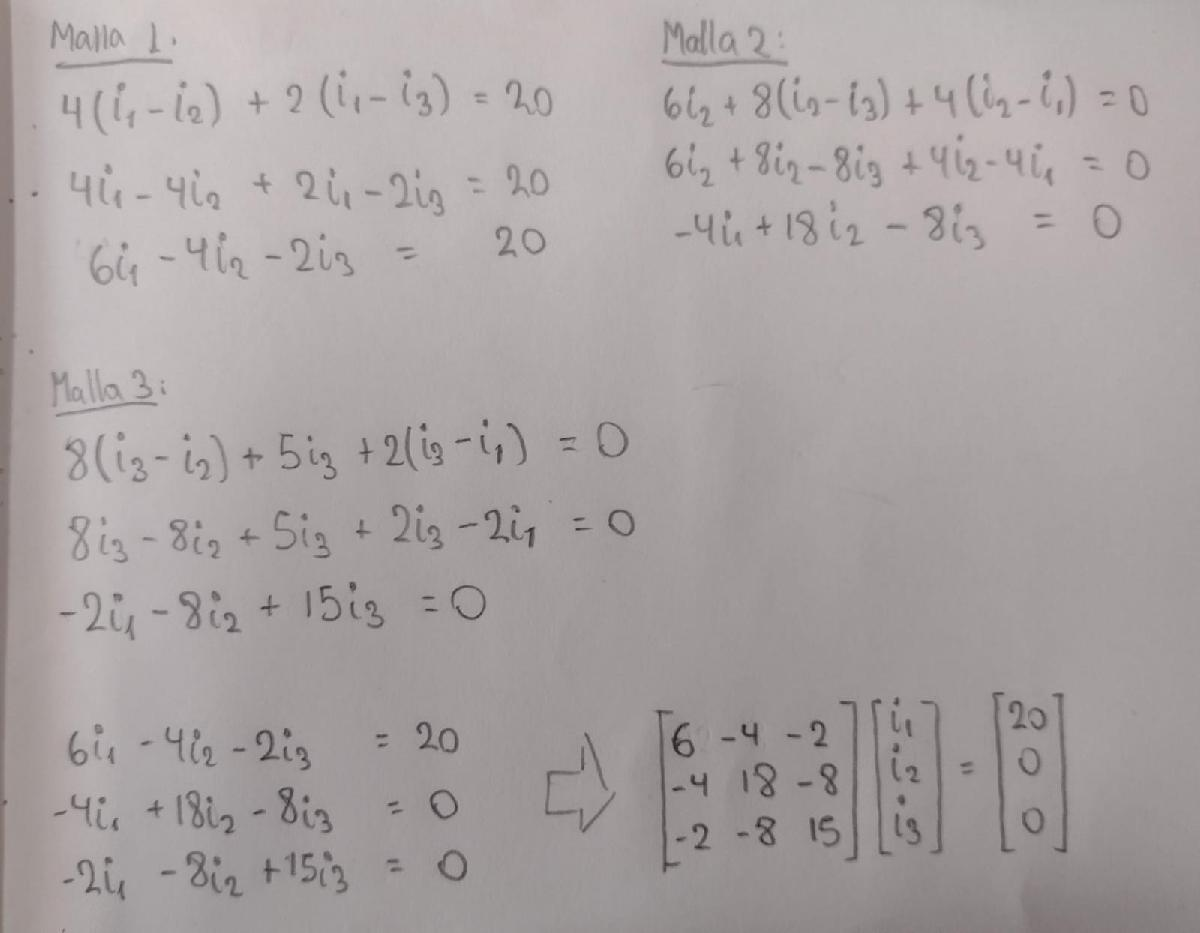

A = [6 -4 -2; -4 18 -8; -2 -8 15];
b = [20 0 0]';

fprintf("Matriz A\n")

Matriz A


disp(A)

     6    -4    -2
    -4    18    -8
    -2    -8    15




fprintf("Matriz b\n")

Matriz b


disp(b)

    20
     0
     0



x0 = [1 1 1]';
Tol = 1e-3;

gs = gausseidel(A,b,x0,Tol);

fprintf("Gauss Seidel\ni1 = %f\ni2 = %f\ni3 = %f\n", gs(end, 1:3))

Gauss Seidel
i1 = 5.172446
i2 = 1.907525
i3 = 1.707006


# Funciones

1A.1. Función arctan(x) con la aproximación de Taylor

function sol = arctan_taylor_it(x, n)
    sol = 0;

    for i = 0:n
        sol = sol + (-1)^i * (x^(2*i + 1))/(2*i + 1);
    end
end

1A.1. Función para hallar la cantidad de términos necesarios para ciertas cifras significativas

function sol = arctan_taylor_nterm(x, n)
    nterm = 0;
    anterior = arctan_taylor_it(x, nterm);
    delta = 1;

    while (delta > 5 * 10^-n)   
        nterm = nterm + 1;
        actual = arctan_taylor_it(x, nterm);
        delta = abs(actual - anterior)/abs(actual);
        anterior = actual;
    end

    sol = nterm + 1;
end

1A.2. Función para calcular binario IEEE-754 precisión simple

function x = simple2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 24 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 127 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

1A.2. Función para calcular binario IEEE-754 precisión doble

function x = double2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 53 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 1023 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

1A.2. Función para convertir de binario IEEE - 754 presición simple a decimal

function x = binary2dec_simple(b)
    s = b(1);
    e = b(2:9);
    m = b(10:32);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-127)*(1+dec_m);
end

1A.2. Función para convertir de binario IEEE - 754 presición doble a decimal

function x = binary2dec_double(b)
    s = b(1);
    e = b(2:12);
    m = b(13:64);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-1023)*(1+dec_m);
end

1B.1. Bisección con Tolerancia

function z = biseccion(f,a,b,Tol)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [a b c f(a) f(b) f(c) error];
    N = ceil(log((b-a)/(2*Tol))/log(2));

    fprintf('Se necesita %d iteraciones\n', N)
    
    while error>Tol
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        
        c = (a+b)/2;
        error = (b-a)/2;
        z = [z; a b c f(a) f(b) f(c) error];
    end

end

1B.1. Newton con tolerancia

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error > Tol
        x1 = x0 - f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end

1B.2. Punto Fijo con tolerancia

function z = puntofijo(g, x0, tol)
    error = 1;
    z = [x0 error];

    while error > tol
        x1 = g(x0);
        error = abs(x1 - x0)/abs(x1);
        z = [z; x1 error];
        x0 = x1;
    end
end

1C. Función de Newton Raphson

function z = newtonraphson(F, x0, Tol)
    syms x y
    dF = jacobian(F(x,y),[x,y]);
    df_fun = matlabFunction(dF);
    error=1;
    z = [x0' error];

    while error>Tol
        x1 = x0 - inv(df_fun(x0(1),x0(2))) * F(x0(1),x0(2));
        error = norm(x1 - x0, "inf")/norm(x1, "inf");
        z = [z; x1' error];
        x0 = x1;
    end
end

1D.1. Criterio de convergencia por Diagonal estrictamente Dominante

function op = diagdom(A)
    % op = 0 si es Estrictamente Dominante
    % op = 1 si no lo es


    [m,n] = size(A);
    op = 0;
    
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 1;
                break;
            end
        end
    end
end

1.D1. Función de Jacobi  con tolerancia

function z = jacobi(A,b,x0,Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tj = inv(D)*(L+U);
    cj = inv(D)*b;

    error = 1;

    z = [x0' error];

    while error>Tol
        x1 = Tj*x0 + cj; 
        error = norm(x1-x0, "inf")/norm(x1, "inf");
        z = [z; x1' error];
        x0 = x1;
    end
end

1.D2., 1.E. Función de eliminación gaussiana

function [Ea,nb] = gauss(A,b)
    [m,n] = size(A);
    Aa = [A b];

    for k = 1:n-1
        pivo = Aa(k,k);

        for j = k+1:n
            mjk = Aa(j,k)/pivo;
            Aa(j,:) = Aa(j,:) - mjk*Aa(k,:);
        end
    end

    Ea = Aa(:,1:n);
    nb = Aa(:,n+1);
end

1.D2. 1.E. Función de sustitución regresiva

function [x] = sustireg(Ea,b)
    U = triu(Ea);
    % U: Matriz triangular superior
    [m,n] = size(U);
    x = zeros(n,1);

    for k = n:-1:1
        x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
    end
end


1.D2. Función radio espectral

function re = radio_espectral(T)
    re = max(abs(eig(T)));
end

1.D2., 1.E. Función de Gauss Seidel [tolerancia]

function z = gausseidel(A, b, x0, Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z = [x0' error];

    while error > Tol
        x1 = Tgs*x0 + cgs;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z;x1' error];
        x0 = x1;
    end
end